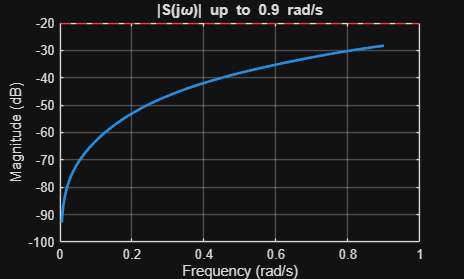

clc
clear all

syms theta w
theta_max = 0.07;
s = tf('s');
theta = 8;
%assume(theta>0 & theta<theta_max);

G0 = ((200) / (10*s + 1)) * (1 / (0.05*s + 1)^2);

G_nom = exp(-theta*s) * G0;

K = 0.5 * ((s+2)/s) * ((0.05*s + 1)/(0.005*s + 1));

% Open-loop
L_nom = K * G_nom;

% Sensitivity function S(s) = 1 / (1 + L)
S_nom = 1 / (1 + L_nom);

% Complementary sensitivity T(s) = L / (1 + L)
T_nom = L_nom / (1 + L_nom);

w = linspace(0, 0.9, 200);  % 200 points from 0 to 0.9 rad/s
[mag, phase] = bode(S_nom, w);

% mag will be a 3D array if S_nom is SISO, it should be (1x1xlength(w)).
% We can reshape it for convenience:
mag_db = 20*log10(squeeze(mag));  % magnitude in dB

figure;
plot(w, mag_db, 'LineWidth', 2);
grid on; hold on;
yline(-20, '--r', 'Magnitude = 0.1 (-20 dB)');
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('|S(j\omega)| up to 0.9 rad/s');

syms s theta

G0 = ((200) / (10*s + 1)) * (1 / (0.05*s + 1)^2);

G_nom = exp(-theta*s) * G0;

K = 0.5 * ((s+2)/s) * ((0.05*s + 1)/(0.005*s + 1));

vpa((G_nom - G0)/G0)

$$ans = -0.005\,\left(\frac{200.0}{\left(10.0\,s+1.0\right)\,{\left(0.05\,s+1.0\right)}^{2}}-\frac{200.0\,{\mathrm{e}}^{-1.0\,s\,\theta }}{\left(10.0\,s+1.0\right)\,{\left(0.05\,s+1.0\right)}^{2}}\right)\,\left(10.0\,s+1.0\right)\,{\left(0.05\,s+1.0\right)}^{2}$$